% Rocky_closed_loop_poles_23.m
%
% 1) Symbolically calculates closed loop transfer function of a disturbannce
% rejection PI control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target) poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp  to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this, the control constants can be found exactly 
%
% 5) Plot impulse and step response to see closed-loop behavior. 
%
% based on code by SG. last modified 2/25/23 CL

clear all; 
% close all;

syms s a b l g Kp Ki    % define symbolic variables

Hvtheta = -s/l/(s^2-g/l)      % TF from velocity to angle of pendulum

$$Hvtheta = \frac{s}{l\,\left(\frac{g}{l}-s^{2}\right)}$$


K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a)                   % TF of motor (1st order model) 

$$M = \frac{a\,b}{a+s}$$

%  M = 1;                       % TF without motor
%
%  
% closed loop transfer function from disturbance d(t)totheta(t)
Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)}-1}$$


pretty(simplify(Hcloop))       % to display the total transfer function

              1
- ------------------------
     a b (Ki + Kp s)
  -------------------- - 1
                2
  (a + s) (- l s  + g)




% Substitute parameters and solve
% system parameters
g = 9.81;
l = 0.436   %effective length 

l = 0.4360

a = 13.83;           %nominal motor parameters
b = 0.0036;        %nominal motor parameters

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{0.1142\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{\left(s+13.8300\right)\,\left(s^{2}-22.5000\right)}+1}$$


p12_real = 0

p12_real = 0

p12_im = -0.1 * pi

p12_im = -0.3142

wn = sqrt(p12_real^2 + p12_im^2)

wn = 0.3142



% p12_im = -1*pi
% wn = 4.8
% p12_real = sqrt(wn^2 - p12_im^2)


% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 
p1 = p12_real + p12_im*i    % dominant pole pair

p1 = 0.0000 - 0.3142i

p2 = p12_real - p12_im*i    % dominant pole pair 

p2 = 0.0000 + 0.3142i

p3 = -1

p3 = -1



% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increase
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

$$tgt\_char\_poly = \left(s-0.3142\,\mathrm{i}\right)\,\left(s+0.3142\,\mathrm{i}\right)\,\left(s+1\right)$$

npoly = 3

npoly = 3



% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = 545\,\left(100\,s+1383\right)\,\left(2\,s^{2}-45\right)$$

$$d = 12447\,\mathrm{Ki}-2452500\,s+12447\,\mathrm{Kp}\,s+1507470\,s^{2}+109000\,s^{3}-33918075$$


% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccc} 12447\,\mathrm{Ki}-33918075 & 12447\,\mathrm{Kp}-2452500 & 1507470 & 109000 \end{array}\right)$$


% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccc} 0.1142\,\mathrm{Ki}-311.1750 & 0.1142\,\mathrm{Kp}-22.5000 & 13.8300 & 1 \end{array}\right)$$


% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \left(\begin{array}{cccc} 0.0987 & 0.0987 & 1 & 1 \end{array}\right)$$


% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:npoly-1) == coeffs_tgt(1:npoly-1),  Kp, Ki)

solutions = struct with fields:
    Kp: [1×1 sym]
    Ki: [1×1 sym]



% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 197.8997

Ki = double(solutions.Ki)

Ki = 2.7259e+03


% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end
closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), npoly )

$$closed\_loop\_poles = \left(\begin{array}{c} -13.8234\\ -0.0033-0.0862\,\mathrm{i}\\ -0.0033+0.0862\,\mathrm{i} \end{array}\right)$$



% Plot impulse response of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);

TFH =
 
  1.09e06 s^4 + 1.507e07 s^3 - 2.453e07 s^2 - 3.392e08 s
  ------------------------------------------------------
   1.09e06 s^4 + 1.507e07 s^3 + 1.076e05 s^2 + 112023 s
 
Continuous-time transfer function.



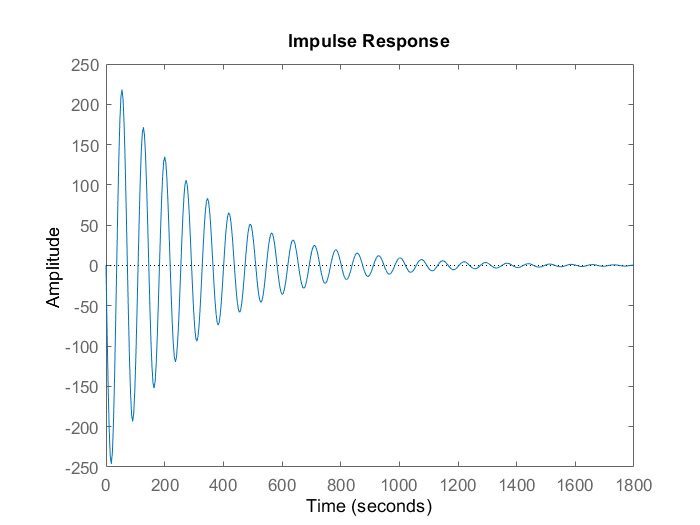

%     figure (1)
    impulse(TFH);   %plot the impulse reponse
    hold on

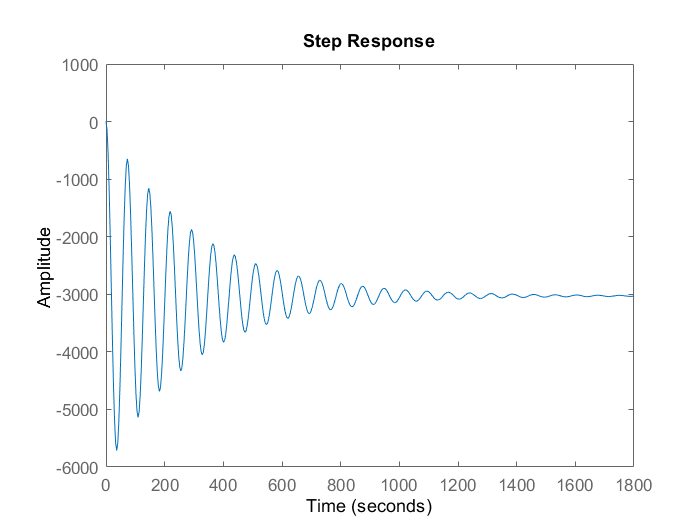

    
    figure
    step(TFH);

%     figure(2)
%     step(TFH)       %plot the step response
    